# Overview of communication systems

### What is communication?

Transfer information from one point in space-time to another. 

- Information is quantified using "Entropy" which is a topic within information theory. 

### Following the bits through a system

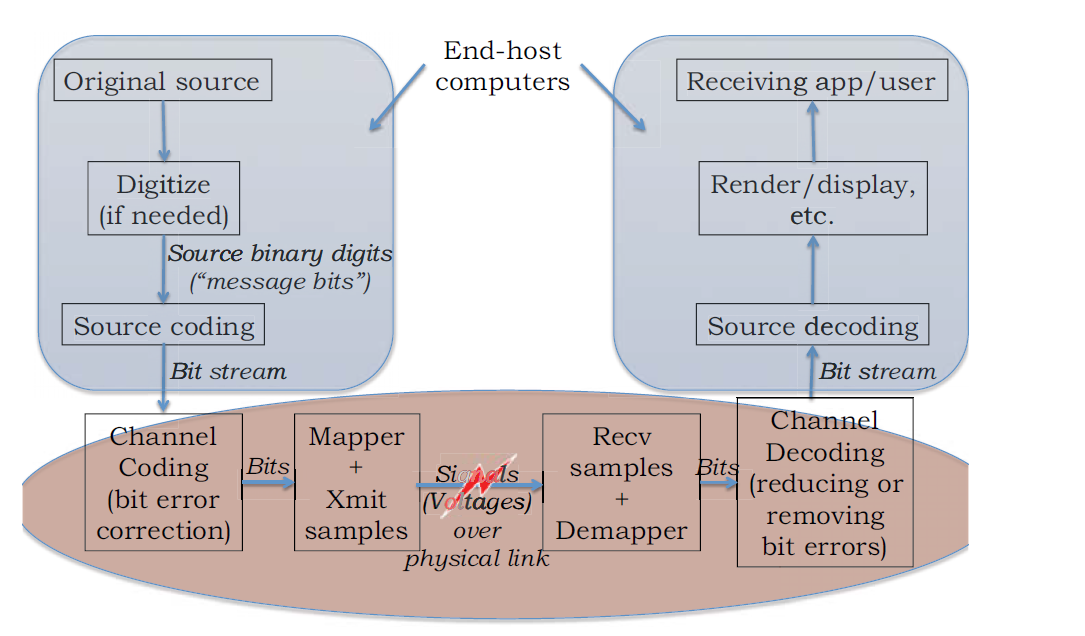

Generate some data bits 

n = 15; % Codeword length
k = 11; % Message length
data = randi([0 1],k,1);
data'

ans =      1     1     0     1     1     0     0     0     1     0     1


Add parity bits (Channel coding) 

encData = encode(data,n,k,'hamming/binary');
encData'

ans =      1     0     1     1     1     1     0     1     1     0     0     0     1     0     1


Simulating a binary symmetric channel (flipping random bits)

errLoc = randerr(1,n)

errLoc =      0     0     0     0     0     0     0     0     0     1     0     0     0     0     0


encData = mod(encData + errLoc',2);
encData'

ans =      1     0     1     1     1     1     0     1     1     1     0     0     1     0     1


Decode the corrupted sequence. Observe that the decoder has correctly recovered the message.

decData = decode(encData,n,k,'hamming/binary');
numerr = biterr(data,decData)'

numerr = 0

data'

ans =      1     1     0     1     1     0     0     0     1     0     1


decData'

ans =      1     1     0     1     1     0     0     0     1     0     1


#### Documentation pages for source coding and channel coding

[PHY Components](https://www.mathworks.com/help/comm/comm-phy-components.html?s_tid=CRUX_lftnav)

#### Simulink model to show mapping to signals

open_system('qam_modulation\square_pulse_baseband.slx')

#### Documentation pages for mapping bits to signals 

[Filtering](https://www.mathworks.com/help/comm/filtering.html?s_tid=CRUX_lftnav)

### Where do Antennas fit in?

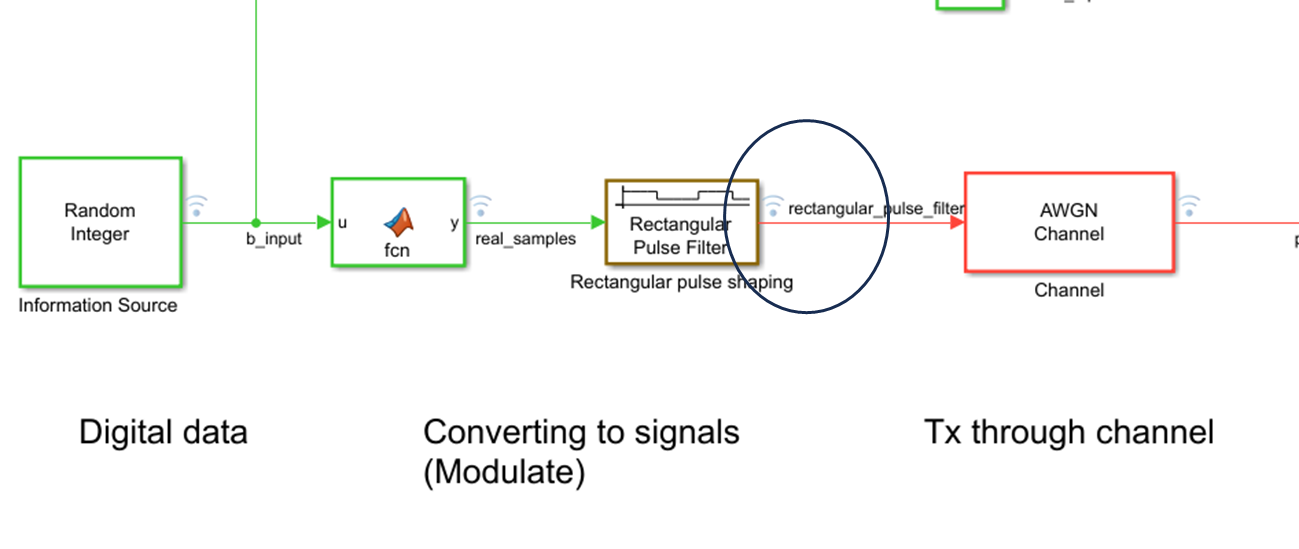

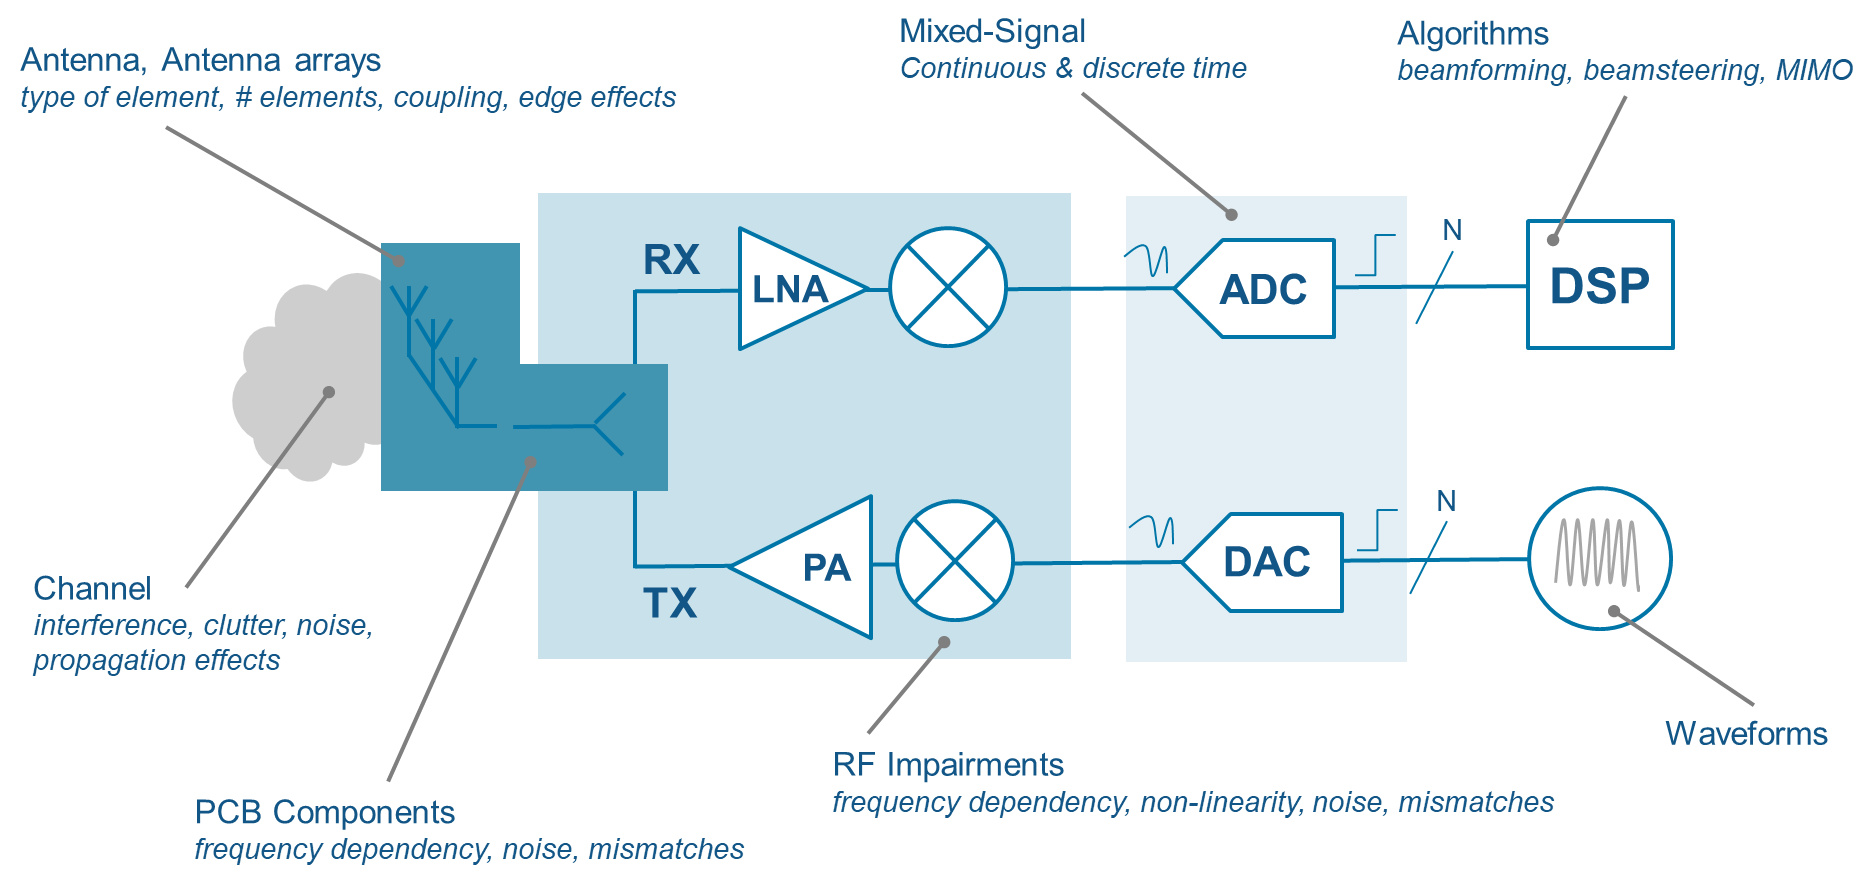

#### Some commonly used Antennas

- [Wiki page on Antenns types](https://en.wikipedia.org/wiki/Antenna_types)

- [Microstrip Antennas and Arrays](https://en.wikipedia.org/wiki/Microstrip_antenna)

- [MATLAB Antenna Catalog](https://www.mathworks.com/help/antenna/antenna-catalog.html)  

- [MATLAB Antenna Array Catalog](https://www.mathworks.com/help/antenna/array-catalog.html?s_tid=CRUX_lftnav)

#### Example of a workflow from a customer engagment

“we would like to use a microstrip patch array as a feed antenna to an offset reflector. Hence, we need to establish the reflector model and optimize the overall pattern by adjusting the patch array radiation pattern. Can the Matlab toolboxes accomplish this?”

Set up the antenna structure. 

- Setting up the antenna can be done by i) selecting/designing the patch element, ii) creating a patch array using the element, and iii) setting up the patch array as a feed to a reflector antenna.

- The example on [Design and Analyze Parabolic-Reflector-Backed Wideband Eggcrate Array](https://www.mathworks.com/help/antenna/ug/parabolic-reflector-backed-wideband-eggcrate-array.html) shows the above workflow with specific selections for each step above. 

- More on [Antenna and Array analysis](https://www.mathworks.com/help/antenna/antenna-analysis.html?s_tid=CRUX_lftnav) 

- Note: The [Antenna Designer](https://www.mathworks.com/help/antenna/ref/antennadesigner-app.html) and the [Antenna Array Designer](https://www.mathworks.com/help/antenna/ref/antennaarraydesigner-app.html) apps provide GUIs for the above workflows. A useful feature I want to highlight is that once you have a preliminary design, you can select “Generate script”, which will generate the MATLAB code needed to replicate the design performed interactively in the GUIs. 

### What is taught in courses?

Let us look at some syllabi 

### Positioning 

Competitors: 

- Ansys HFSS (High frequency structural simulator)

- COMSOL Multiphysics

- CST microwave 

- Altair fico 

- Keysight ADS (for RF simulation) 

How does MATLAB differ? 

- Small learning curve and easy to use.

- The other software are very accurate but expensive (COMSOL multiphysics is $60K a piece!). You can obtain reasonably accurate results with MATLAB Antenna toolbox. 

- MATLAB is better positioned for end-to-end simulations of the entire system. Often, engineers use MATLAB as a first pass to design a system and then use other software to fine-tune. 

### Book to feature

[Antenna and EM Modeling with MATLAB Antenna Toolbox, 2nd edition](https://www.mathworks.com/academia/books/antenna-and-em-modeling-with-matlab-makarov.html)